## Uribe & Yue (2006) 

## Table 6.1, Step-by-Step

We build this incrementally: first the book's own Table 6.1 (manually transcribed, for reference), then Table 6.1.A (our baseline panel replication, Rus AR(1) bug fixed but still only 31 quarters available), then Table 6.1.B (same thing but with the Rus AR(1) horizon extended using the longer external series), then one table per country, restricting the sample to a single country at a time.

## Section 0: Setup

clear; close all; clc;
folder     = 'C:\Users\celso\Documents\FGV-EESP\Open macroeconomics\2026\Cap 6 - replication';
datafile   = fullfile(folder, 'statadata.xls');
irsfile    = fullfile(folder, 'irs_data_update.mat');   % contains long_rus

## Original table 6.1 (from SGU)

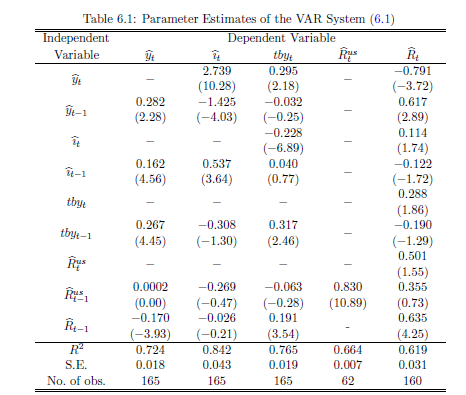

## Section 2: Load the panel (shared by everything below)

opts = detectImportOptions(datafile, 'FileType', 'text', 'Delimiter', '\t');
T = readtable(datafile, opts);

code = T.code; time = T.time;
logydsa = T.logydsa; loginvdsa = T.loginvdsa; tbysa = T.tbysa;
logrus  = T.logrus;  logi = T.logi;    % logi = COUNTRY rate R, not investment

[~, ord] = sortrows([code, time]);
code = code(ord); time = time(ord);
logydsa = logydsa(ord); loginvdsa = loginvdsa(ord);
tbysa = tbysa(ord); logrus = logrus(ord); logi = logi(ord);

logydsalag    = panel_lag(logydsa,   code, 1);
logydsalag2   = panel_lag(logydsa,   code, 2);
loginvdsalag  = panel_lag(loginvdsa, code, 1);
tbysalag      = panel_lag(tbysa,     code, 1);
logruslag     = panel_lag(logrus,    code, 1);
logruslag2    = panel_lag(logrus,    code, 2);
logilag       = panel_lag(logi,      code, 1);
logilag2      = panel_lag(logi,      code, 2);

rowmap = containers.Map( ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag'}, ...
    {1,2,3,4,5,6,7,8,9});
rownames = book_rownames; colnames = book_colnames;

## Section 3: Table 6.1.A -- baseline replication

##  Rus AR(1) (N=31)

Equations 1, 2, 3, 5 are the same fixed-effects IV panel regressions as in SGU. The Rus column is a AR(1): a single deduplicated country's logrus series , with only statadata.xls (1994-2001), N=31.

[b1, se1, res1, ~, r2_1] = panel_fe_iv(logydsa, ...
    {loginvdsalag, tbysalag, logruslag, logilag}, logydsalag, logydsalag2, code, ...
    {'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, 'y');


-- Equation [y], n=165, k=5, within R^2=0.724 --
   loginvdsalag       coef= 0.1626  se=0.0348  t= 4.67
   tbysalag           coef= 0.2677  se=0.0589  t= 4.55
   logruslag          coef= 0.0002  se=0.1960  t= 0.00
   logilag            coef=-0.1701  se=0.0423  t=-4.02
   logydsalag(IV)     coef= 0.2821  se=0.1208  t= 2.34


[b2, se2, res2, ~, r2_2] = panel_fe_iv(loginvdsa, ...
    {logydsa, logydsalag, tbysalag, logruslag, logilag}, loginvdsalag, panel_lag(loginvdsa,code,2), code, ...
    {'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, 'i');


-- Equation [i], n=165, k=6, within R^2=0.842 --
   logydsa            coef= 2.7390  se=0.2606  t= 10.51
   logydsalag         coef=-1.4354  se=0.3482  t=-4.12
   tbysalag           coef=-0.3081  se=0.2324  t=-1.33
   logruslag          coef=-0.2687  se=0.5587  t=-0.48
   logilag            coef=-0.0259  se=0.1183  t=-0.22
   loginvdsalag(IV)   coef= 0.5375  se=0.1443  t= 3.73


[b3, se3, res3, ~, r2_3] = panel_fe_iv(tbysa, ...
    {logydsa, logydsalag, loginvdsa, panel_lag(loginvdsa,code,1), logruslag, logilag}, tbysalag, panel_lag(tbysa,code,2), code, ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, 'tb/y');


-- Equation [tb/y], n=165, k=7, within R^2=0.765 --
   logydsa            coef= 0.2952  se=0.1326  t= 2.23
   logydsalag         coef=-0.0322  se=0.1265  t=-0.25
   loginvdsa          coef=-0.2284  se=0.0324  t=-7.05
   loginvdsalag       coef= 0.0403  se=0.0511  t= 0.79
   logruslag          coef=-0.0626  se=0.2196  t=-0.29
   logilag            coef= 0.1908  se=0.0527  t= 3.62
   tbysalag(IV)       coef= 0.3169  se=0.1257  t= 2.52


[b5, se5, res5, ~, r2_5] = panel_fe_iv(logi, ...
    {logydsa, logydsalag, loginvdsa, panel_lag(loginvdsa,code,1), tbysa, tbysalag, logrus, logruslag}, logilag, logilag2, code, ...
    {'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, 'R');


-- Equation [R], n=160, k=9, within R^2=0.619 --
   logydsa            coef=-0.7906  se=0.2075  t=-3.81
   logydsalag         coef= 0.6168  se=0.2084  t= 2.96
   loginvdsa          coef= 0.1137  se=0.0637  t= 1.78
   loginvdsalag       coef=-0.1219  se=0.0690  t=-1.77
   tbysa              coef= 0.2886  se=0.1518  t= 1.90
   tbysalag           coef=-0.1899  se=0.1441  t=-1.32
   logrus             coef= 0.5008  se=0.3153  t= 1.59
   logruslag          coef= 0.3553  se=0.4755  t= 0.75
   logilag(IV)        coef= 0.6347  se=0.1425  t= 4.45



one_country = code(1);
rus_series = logrus(code==one_country);
rus_time   = time(code==one_country);
[rus_time, o] = sort(rus_time); rus_series = rus_series(o);
rus_lag1 = [NaN; rus_series(1:end-1)];
keepA = ~isnan(rus_series) & ~isnan(rus_lag1);
yA = rus_series(keepA); xA = rus_lag1(keepA); nA = numel(yA);
XcA = [ones(nA,1), xA];
betaA = XcA \ yA;
res_ar1_A = yA - XcA*betaA;
seA = sqrt(diag((res_ar1_A'*res_ar1_A)/(nA-2) * inv(XcA'*XcA))); %#ok<MINV>
b_ar1_A = betaA(2); se_ar1_A = seA(2);
r2_ar1_A = 1 - sum(res_ar1_A.^2)/sum((yA-mean(yA)).^2);
fprintf('\nTable 6.1.A Rus AR(1): N=%d, rho=%.4f (se=%.4f)\n', nA, b_ar1_A, se_ar1_A);


Table 6.1.A Rus AR(1): N=31, rho=0.7452 (se=0.1540)



[c1,t1] = map_to_rows({'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, b1, se1, rowmap);
[c2,t2] = map_to_rows({'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, b2, se2, rowmap);
[c3,t3] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, b3, se3, rowmap);
[c4,t4] = map_to_rows({'logruslag(IV)'}, b_ar1_A, se_ar1_A, rowmap);
[c5,t5] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, b5, se5, rowmap);

coefmat_A  = [c1,c2,c3,c4,c5];
tstatmat_A = [t1,t2,t3,t4,t5];
r2vec_A    = [r2_1, r2_2, r2_3, r2_ar1_A, r2_5];
nobsvec_A  = [numel(res1), numel(res2), numel(res3), nA, numel(res5)];
sevec_A    = [std(res1), std(res2), std(res3), std(res_ar1_A), std(res5)];

fprintf('\n============ TABLE 6.1.A ============\n');


============ TABLE 6.1.A ============


print_table61(rownames, colnames, coefmat_A, tstatmat_A, r2vec_A, sevec_A, nobsvec_A);


Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      2.7390      0.2952           -     -0.7906
                             (10.51)      (2.23)                 (-3.81)
y_{t-1}           0.2821     -1.4354     -0.0322           -      0.6168
                  (2.34)     (-4.12)     (-0.25)                  (2.96)
i_t                    -           -     -0.2284           -      0.1137
                                         (-7.05)                  (1.78)
i_{t-1}           0.1626      0.5375      0.0403           -     -0.1219
                  (4.67)      (3.73)      (0.79)                 (-1.77)
tby_t                  -           -           -           -      0.2886
                                                                  (1.90)
tby_{t-1}         0.2677     -0.3081      0.3169           -     -0.1899
                  (4.55)     (-1.33)      (2.52)                 (-1.32)
Rus_t                  -           -           -  

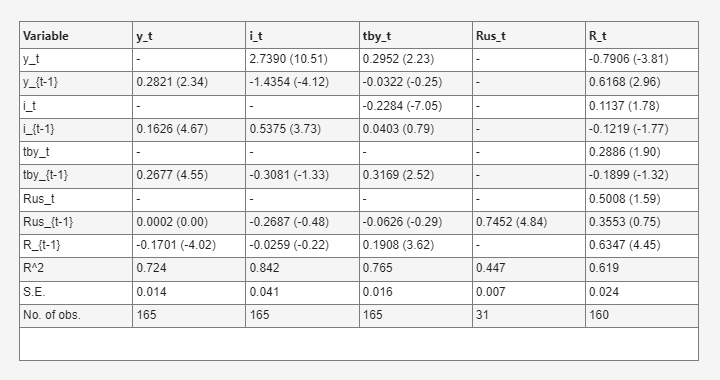

figure_table61(rownames, colnames, coefmat_A, tstatmat_A, r2vec_A, sevec_A, nobsvec_A, 'Table 6.1.A');

*Differences from the book's Table 6.1:*  * Rus column N = 31, not 62 -- statadata.xls only spans 1994Q1-2001Q4; the paper used a longer, separate 1987-2002 sample just for this equation, which we don't have in this file. * Rus_{t-1} rho is noticeably different from 0.830 given the shorter, different-vintage sample -- expect this to move around. * y, i, tb/y, R equation coefficients are close to the book's but not identical -- panel composition (8 countries here vs. 7 in the book, we have an extra one: Venezuela) and possible small data-vintage differences account for the gap. * R^2, S.E. for equations 1/2/3/5 should be close to the book's since those don't depend on the Rus-series fix at all.

## Section 3b: Impulse Response Functions (Table 6.1.A data)

Following SGU procedure: system (6.1) is recursive (Cholesky) by construction -- that's exactly what "A lower-triangular, unit diagonal" in their eq. (6.1) means, and it's already baked into which variables appear contemporaneously vs. only lagged in equations 1-5 above:

- y sees no contemporaneous regressor; 

- i sees contemporaneous y; 

- tb/y sees contemporaneous y and i; 

- Rus sees nothing contemporaneous -- it's the exogenous univariate AR(1); 

- R sees everything contemporaneously, since it's ordered last.

So we don't need to re-derive anything: just reassemble our already estimated Table 6.1.A coefficients into structural matrices A, B with $A*z_t = B*z_{t-1} + eps_t,      z_t = [y_t, i_t, tby_t, Rus_t, R_t]$ and iterate the reduced-form companion matrix Phi = A^{-1}*B forward from each shock's impact vector A^{-1}*e_j. This is the standard Cholesky-SVAR IRF formula and reproduces exactly what the book's Figures 6.2 (country-spread shock = shock to the R equation, ordered last) and 6.3 (US-interest-rate shock = shock to the Rus equation) report -- point estimates only; see the note at the end of this section on why error bands are not included here.

A = eye(5);
B = zeros(5,5);

order: z = [y, i, tby, rus, R]

eq1 y: y_t = b1(1)*i_{t-1} + b1(2)*tby_{t-1} + b1(3)*rus_{t-1} + b1(4)*r_{t-1} + b1(5)*y_{t-1}

B(1,2)=b1(1); B(1,3)=b1(2); B(1,4)=b1(3); B(1,5)=b1(4); B(1,1)=b1(5);

eq2 i: i_t = b2(1)*y_t + b2(2)*y_{t-1} + b2(3)*tby_{t-1} + b2(4)*rus_{t-1} + b2(5)*r_{t-1} + b2(6)*i_{t-1}

A(2,1) = -b2(1);
B(2,1)=b2(2); B(2,3)=b2(3); B(2,4)=b2(4); B(2,5)=b2(5); B(2,2)=b2(6);

eq3 tby: tby_t = b3(1)*y_t + b3(2)*y_{t-1} + b3(3)*i_t + b3(4)*i_{t-1} + b3(5)*rus_{t-1} + b3(6)*r_{t-1} + b3(7)*tby_{t-1}

A(3,1) = -b3(1); A(3,2) = -b3(3);
B(3,1)=b3(2); B(3,2)=b3(4); B(3,4)=b3(5); B(3,5)=b3(6); B(3,3)=b3(7);

eq4 rus: rus_t = rho * rus_{t-1}   (Table 6.1.A's restricted AR(1), N=31)

B(4,4) = b_ar1_A;

eq5 R: r_t = b5(1)*y_t + b5(2)*y_{t-1} + b5(3)*i_t + b5(4)*i_{t-1} + b5(5)*tby_t + b5(6)*tby_{t-1} + b5(7)*rus_t + b5(8)*rus_{t-1} + b5(9)*r_{t-1}

A(5,1) = -b5(1); A(5,2) = -b5(3); A(5,3) = -b5(5); A(5,4) = -b5(7);
B(5,1)=b5(2); B(5,2)=b5(4); B(5,3)=b5(6); B(5,4)=b5(8); B(5,5)=b5(9);

Ainv = inv(A); 
Phi  = Ainv * B;
Hmax = 24;

irf_spread = compute_irf(Ainv, Phi, 5, Hmax);   % shock to R eq (ordered last) = country-spread shock
irf_usrate = compute_irf(Ainv, Phi, 4, Hmax);   % shock to Rus eq = US-interest-rate shock
hz = (0:Hmax)';

Figure 6.2 style: country-spread shock

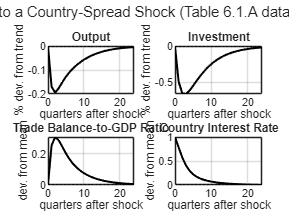

figure('Name','IRF to Country-Spread Shock (Table 6.1.A)','Position',[100 100 800 600]);
subplot(2,2,1); plot(hz, irf_spread(:,1),'k-','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(2,2,2); plot(hz, irf_spread(:,2),'k-','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(2,2,3); plot(hz, irf_spread(:,3),'k-','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;

subplot(2,2,4); plot(hz, irf_spread(:,5),'k-','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
sgtitle('Impulse Response to a Country-Spread Shock (Table 6.1.A data) -- cf. book Fig. 6.2');

---- Figure 6.3 style: US-interest-rate shock ----

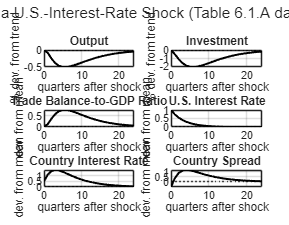

spread_irf = irf_usrate(:,5) - irf_usrate(:,4);   % R - Rus = country spread
figure('Name','IRF to US-Interest-Rate Shock (Table 6.1.A)','Position',[100 100 900 700]);
subplot(3,2,1); plot(hz, irf_usrate(:,1),'k-','LineWidth',1.5); yline(0,'k:');
title('Output'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(3,2,2); plot(hz, irf_usrate(:,2),'k-','LineWidth',1.5); yline(0,'k:');
title('Investment'); xlabel('quarters after shock'); ylabel('% dev. from trend'); grid on;
subplot(3,2,3); plot(hz, irf_usrate(:,3),'k-','LineWidth',1.5); yline(0,'k:');
title('Trade Balance-to-GDP Ratio'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
subplot(3,2,4); plot(hz, irf_usrate(:,4),'k-','LineWidth',1.5); yline(0,'k:');
title('U.S. Interest Rate'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
subplot(3,2,5); plot(hz, irf_usrate(:,5),'k-','LineWidth',1.5); yline(0,'k:');
title('Country Interest Rate'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;

subplot(3,2,6); plot(hz, spread_irf,'k-','LineWidth',1.5); yline(0,'k:');
title('Country Spread'); xlabel('quarters after shock'); ylabel('dev. from mean'); grid on;
sgtitle('Impulse Response to a U.S.-Interest-Rate Shock (Table 6.1.A data) -- cf. book Fig. 6.3');

*Obs:* the book's figures show two-standard-error bands computed by the delta method (the Jacobian of the IRF, a nonlinear function of A and B, with respect to all the underlying VAR coefficients -- that requires the full joint covariance matrix across ALL FIVE equations, not just each equation's own se's, which is a substantially bigger undertaking than the point estimates above). The IRFs plotted here are point estimates only. If you want error bands, a pragmatic alternative to hand-deriving the delta-method Jacobian is a residual/pairs bootstrap (resample the panel and re-run Table 6.1.A's whole pipeline many times, then take the 2.5/97.5 percentiles of the resulting IRFs at each horizon) 

## Section 3c: Export target IRFs for Dynare IRF matching

Produces a single .mat file that

DSGE_uribe_yue_IRFmatch.mod loads through its matched_irfs; block. This version matches Uribe and Yue (2006, JIE), Section 3.1.4 exactly, not the earlier 1-std-dev normalization: 

  "we consider the first 24 quarters of the impulse response functions   of 4 variables (output, investment, the trade balance, and the country   interest rate), to 2 shocks (the US-interest-rate shock and the   country-spread shock). Thus, we are setting 4 parameter values to   match 192 points." (4 vars x 2 shocks x 24 quarters = 192)

Two things changed relative to the earlier version of this script:

1. ONLY 4 VARIABLES ARE MATCHED: y, i, tby, R. The paper's VAR has 5   variables (y, i, tby, Rus, R), but Rus itself is NOT one of the 4   matched series -- it is only ever a REGRESSOR / shock source, never a   target. rus_eps_r and rus_eps_rus are therefore no longer exported.

2. THE SHOCK SIZE IS 0.01, NOT A ONE-STANDARD-DEVIATION SHOCK. Figure 2's  caption describes "a unit innovation" and Figure 3's describes "a one  percentage point increase" -- both figures' interest-rate panels peak near 1 on an axis explicitly labeled in percentage points, which is exactly what you get from a 0.01 LOG-unit shock displayed on a x100-scaled axis  (log(1.01+0.01)-log(1.01) = 0.0099 =~ 0.01). This is   a fixed, deliberate normalization for the estimation exercise, not  the shocks' true estimated standard deviations -- those are stated  directly in the paper's text (eqs. 13, 15) as 0.031 for epsilon^r and    0.007 for epsilon^rus, and are used elsewhere in the paper (variance    decompositions), not for this IRF-matching step.

Build the 4-variable, 24-quarter target, at the paper's 0.01 shock size

SHOCK_SIZE = 0.01;   % matches "unit innovation" / "one percentage point increase"
HORIZON    = 24;     % "the first 24 quarters" -- rows 1:24 of irf_spread/irf_usrate
                      % (row 1 = impact = horizon 0, matching Dynare's own
                      % oo_.irfs indexing convention)

% Column mapping in irf_spread / irf_usrate: [y, i, tby, rus, R]
%   column 1 -> yy (output)     column 2 -> iv (investment)
%   column 3 -> tby             column 5 -> r (country rate)
%   (column 4, rus, is intentionally skipped -- not a matched variable)
% Shock mapping: irf_spread (shock to the R equation) -> Dynare's eps_r
%                irf_usrate (shock to the Rus equation) -> Dynare's eps_rus

yy_eps_r  = irf_spread(1:HORIZON,1) * SHOCK_SIZE;
iv_eps_r  = irf_spread(1:HORIZON,2) * SHOCK_SIZE;
tby_eps_r = irf_spread(1:HORIZON,3) * SHOCK_SIZE;
r_eps_r   = irf_spread(1:HORIZON,5) * SHOCK_SIZE;

yy_eps_rus  = irf_usrate(1:HORIZON,1) * SHOCK_SIZE;
iv_eps_rus  = irf_usrate(1:HORIZON,2) * SHOCK_SIZE;
tby_eps_rus = irf_usrate(1:HORIZON,3) * SHOCK_SIZE;
r_eps_rus   = irf_usrate(1:HORIZON,5) * SHOCK_SIZE;

%% Reference only: this replication's own empirical shock s.d.'s
% NOT used for the matching itself (the paper's stated 0.031 / 0.007 are
% hardcoded directly in the .mod file instead) -- kept here purely to compare 
% Table 6.1.A's own residual s.d.'s against the paper's
% reported values, as a check on how closely this replication's shorter,
% differently-composed panel lines up with the original estimation.

se_r_replication_estimate   = sevec_A(5);   % R equation residual s.d.
se_rus_replication_estimate = sevec_A(4);   % Rus AR(1) residual s.d.

fprintf('\nReference check -- this replication''s own residual s.d.''s vs. the paper''s:\n');


Reference check -- this replication's own residual s.d.'s vs. the paper's:


fprintf('  R equation:   this replication = %.4f,  paper (eq. 13) = 0.031\n', se_r_replication_estimate);

  R equation:   this replication = 0.0242,  paper (eq. 13) = 0.031


fprintf('  Rus AR(1):    this replication = %.4f,  paper (eq. 15) = 0.007\n', se_rus_replication_estimate);

  Rus AR(1):    this replication = 0.0067,  paper (eq. 15) = 0.007


fprintf('(Differences are expected: Table 6.1.A uses a shorter sample, N=31 vs.\n');

(Differences are expected: Table 6.1.A uses a shorter sample, N=31 vs.


fprintf(' the paper''s N=62 for the Rus equation, and 8 countries vs. 7 for the panel.)\n');

 the paper's N=62 for the Rus equation, and 8 countries vs. 7 for the panel.)



%% Save

save('IRF_target_uribe_yue.mat', ...
    'yy_eps_r','iv_eps_r','tby_eps_r','r_eps_r', ...
    'yy_eps_rus','iv_eps_rus','tby_eps_rus','r_eps_rus', ...
    'SHOCK_SIZE','HORIZON', ...
    'se_r_replication_estimate','se_rus_replication_estimate','hz');

fprintf('\nSaved 8 target IRFs (4 variables x 2 shocks x %d quarters = %d points)\n', ...
    HORIZON, 4*2*HORIZON);


Saved 8 target IRFs (4 variables x 2 shocks x 24 quarters = 192 points)


fprintf('to IRF_target_uribe_yue.mat\n');

to IRF_target_uribe_yue.mat


## Section 4: Table 6.1.B -- extend the Rus horizon with irs_data_update.mat

Same y/i/tby/R equations as 6.1.A (unchanged -- they don't get more data just because Rus does). Only the Rus AR(1) changes: instead of the 31 quarters in statadata.xls, we use long_rus from irs_data_update.mat, restricted to the paper's stated 1987-2002 window.

irs = load(irsfile);
long_rus = irs.long_rus;   % [time, value] columns, quarterly, 1948.25-2013.75
lr_time = long_rus(:,1); lr_val = long_rus(:,2);
winmask = lr_time >= 1987.0 & lr_time <= 2002.75;
lr_time_w = lr_time(winmask); lr_val_w = lr_val(winmask);
[lr_time_w, o] = sort(lr_time_w); lr_val_w = lr_val_w(o);

yB = lr_val_w(2:end); xB = lr_val_w(1:end-1); nB = numel(yB);
XcB = [ones(nB,1), xB];
betaB = XcB \ yB;
res_ar1_B = yB - XcB*betaB;
seB = sqrt(diag((res_ar1_B'*res_ar1_B)/(nB-2) * inv(XcB'*XcB))); %#ok<MINV>
b_ar1_B = betaB(2); se_ar1_B = seB(2);
r2_ar1_B = 1 - sum(res_ar1_B.^2)/sum((yB-mean(yB)).^2);
fprintf('\nTable 6.1.B Rus AR(1): N=%d, rho=%.4f (se=%.4f)\n', nB, b_ar1_B, se_ar1_B);


Table 6.1.B Rus AR(1): N=63, rho=0.9612 (se=0.0473)



[c4B,t4B] = map_to_rows({'logruslag(IV)'}, b_ar1_B, se_ar1_B, rowmap);
coefmat_B  = [c1,c2,c3,c4B,c5];
tstatmat_B = [t1,t2,t3,t4B,t5];
r2vec_B    = [r2_1, r2_2, r2_3, r2_ar1_B, r2_5];
nobsvec_B  = [numel(res1), numel(res2), numel(res3), nB, numel(res5)];
sevec_B    = [std(res1), std(res2), std(res3), std(res_ar1_B), std(res5)];

fprintf('\n============ TABLE 6.1.B ============\n');


============ TABLE 6.1.B ============


print_table61(rownames, colnames, coefmat_B, tstatmat_B, r2vec_B, sevec_B, nobsvec_B);


Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      2.7390      0.2952           -     -0.7906
                             (10.51)      (2.23)                 (-3.81)
y_{t-1}           0.2821     -1.4354     -0.0322           -      0.6168
                  (2.34)     (-4.12)     (-0.25)                  (2.96)
i_t                    -           -     -0.2284           -      0.1137
                                         (-7.05)                  (1.78)
i_{t-1}           0.1626      0.5375      0.0403           -     -0.1219
                  (4.67)      (3.73)      (0.79)                 (-1.77)
tby_t                  -           -           -           -      0.2886
                                                                  (1.90)
tby_{t-1}         0.2677     -0.3081      0.3169           -     -0.1899
                  (4.55)     (-1.33)      (2.52)                 (-1.32)
Rus_t                  -           -           -  

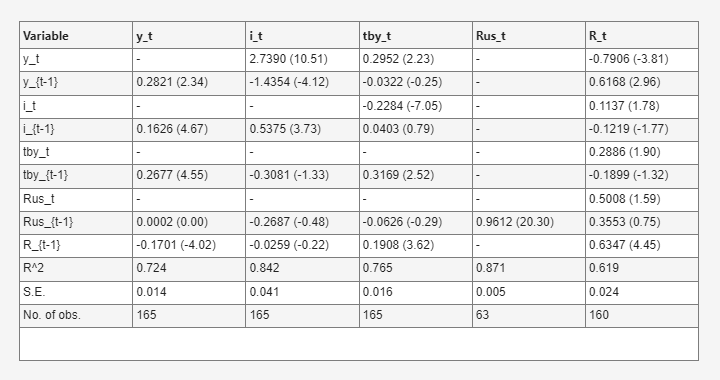

figure_table61(rownames, colnames, coefmat_B, tstatmat_B, r2vec_B, sevec_B, nobsvec_B, 'Table 6.1.B');

*Differences from Table 6.1.A:*  * Only the Rus column changes -- y, i, tb/y, R columns are identical to 6.1.A by construction (same equations, same data). * N jumps from 31 to whatever irs_data_update.mat's long_rus gives us over 1987-2002 (close to, though not necessarily exactly, the book's N=62 -- depends on exact overlap/availability). * rho for Rus should be noticeably different from both 6.1.A's short- sample estimate and the book's 0.830 -- a longer, differently- constructed series changes the persistence estimate meaningfully.

## Section 5: One table per country

Restrict the same estimator (fixed-effects IV -- with a single country this reduces to plain IV with an intercept, since demeaning by one group's mean is algebraically identical to including a constant) to one country at a time. The Rus column is not re-estimated per country (Rus doesn't vary by country -- it's the same 6.1.A AR(1) every time), shown here for completeness/comparison only.


-- Equation [y Argentina], n=26, k=5, within R^2=0.885 --
   loginvdsalag       coef= 0.1193  se=0.1066  t= 1.12
   tbysalag           coef= 0.5572  se=0.6625  t= 0.84
   logruslag          coef= 0.1558  se=0.9914  t= 0.16
   logilag            coef=-0.6372  se=0.2604  t=-2.45
   logydsalag(IV)     coef= 0.4516  se=0.3467  t= 1.30



-- Equation [i Argentina], n=26, k=6, within R^2=0.959 --
   logydsa            coef= 2.1306  se=0.3530  t= 6.04
   logydsalag         coef=-2.4149  se=0.7016  t=-3.44
   tbysalag           coef= 1.5056  se=1.1407  t= 1.32
   logruslag          coef=-0.9701  se=1.5952  t=-0.61
   logilag            coef=-0.5842  se=0.4592  t=-1.27
   loginvdsalag(IV)   coef= 1.1644  se=0.2577  t= 4.52



-- Equation [tb/y Argentina], n=26, k=7, within R^2=0.901 --
   logydsa            coef= 0.0212  se=0.0912  t= 0.23
   logydsalag         coef=-0.2074  se=0.1040  t=-1.99
   loginvdsa          coef=-0.0680  se=0.0358  t=-1.90
   loginvdsalag       coef= 0.0804  se=0.0430  t= 1.87
   logruslag          coef= 0.4625  se=0.2434  t= 1.90
   logilag            coef=-0.0221  se=0.0616  t=-0.36
   tbysalag(IV)       coef= 0.2755  se=0.2411  t= 1.14



   *** WARNING [R Argentina]: n=26 is small relative to k=9 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [R Argentina], n=26, k=9, within R^2=0.897 --
   logydsa            coef=-1.2878  se=0.2507  t=-5.14
   logydsalag         coef= 0.7459  se=0.4261  t= 1.75
   loginvdsa          coef= 0.2811  se=0.1402  t= 2.01
   loginvdsalag       coef=-0.1484  se=0.1874  t=-0.79
   tbysa              coef= 0.4102  se=0.6590  t= 0.62
   tbysalag           coef=-0.7317  se=0.6163  t=-1.19
   logrus             coef= 1.4104  se=0.8606  t= 1.64
   logruslag          coef= 0.6370  se=0.9373  t= 0.68
   logilag(IV)        coef= 0.5296  se=0.4899  t= 1.08



============ TABLE 6.1.Argentina ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      2.1306      0.0212           -     -1.2878
                              (6.04)      (0.23)                 (-5.14)
y_{t-1}           0.4516     -2.4149     -0.2074           -      0.7459
                  (1.30)     (-3.44)     (-1.99)                  (1.75)
i_t                    -           -     -0.0680           -      0.2811
                                         (-1.90)                  (2.01)
i_{t-1}           0.1193      1.1644      0.0804           -     -0.1484
                  (1.12)      (4.52)      (1.87)                 (-0.79)
tby_t                  -           -           -           -      0.4102
                                                                  (0.62)
tby_{t-1}         0.5572      1.5056      0.2755           -     -0.7317
                  (0.84)      (1.32)      (1.14)                 (-1.19)
Rus_t                  -           -           -  

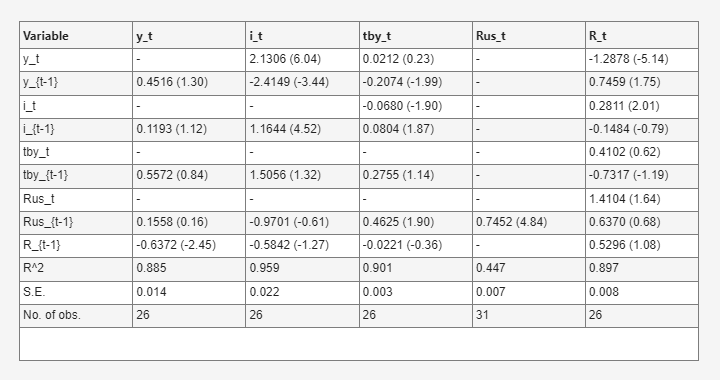


-- Equation [y Brazil], n=29, k=5, within R^2=0.462 --
   loginvdsalag       coef= 0.0695  se=0.1115  t= 0.62
   tbysalag           coef= 0.6127  se=0.2108  t= 2.91
   logruslag          coef= 1.0666  se=0.7338  t= 1.45
   logilag            coef=-0.3668  se=0.1956  t=-1.87
   logydsalag(IV)     coef=-0.1136  se=0.5853  t=-0.19



-- Equation [i Brazil], n=29, k=6, within R^2=-1.748 --
   logydsa            coef= 2.1985  se=2.6885  t= 0.82
   logydsalag         coef=-5.8504  se=19.5642  t=-0.30
   tbysalag           coef= 2.0530  se=4.4070  t= 0.47
   logruslag          coef= 2.9520  se=11.2020  t= 0.26
   logilag            coef=-0.8665  se=3.1449  t=-0.28
   loginvdsalag(IV)   coef= 2.3239  se=6.8693  t= 0.34



-- Equation [tb/y Brazil], n=29, k=7, within R^2=-4.277 --
   logydsa            coef= 0.6426  se=1.7283  t= 0.37
   logydsalag         coef= 0.2578  se=0.8573  t= 0.30
   loginvdsa          coef= 0.1644  se=0.4548  t= 0.36
   loginvdsalag       coef=-0.1637  se=0.4137  t=-0.40
   logruslag          coef=-2.8841  se=5.7569  t=-0.50
   logilag            coef= 0.6225  se=1.3092  t= 0.48
   tbysalag(IV)       coef=-1.4538  se=4.2922  t=-0.34



-- Equation [R Brazil], n=28, k=9, within R^2=0.716 --
   logydsa            coef=-1.3090  se=0.3973  t=-3.29
   logydsalag         coef=-0.3276  se=0.4887  t=-0.67
   loginvdsa          coef= 0.0694  se=0.1391  t= 0.50
   loginvdsalag       coef= 0.1381  se=0.1153  t= 1.20
   tbysa              coef=-1.0374  se=0.9161  t=-1.13
   tbysalag           coef= 1.6872  se=0.5237  t= 3.22
   logrus             coef=-0.0479  se=0.6271  t=-0.08
   logruslag          coef= 2.0465  se=1.1622  t= 1.76
   logilag(IV)        coef= 0.0880  se=0.3373  t= 0.26



============ TABLE 6.1.Brazil ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      2.1985      0.6426           -     -1.3090
                              (0.82)      (0.37)                 (-3.29)
y_{t-1}          -0.1136     -5.8504      0.2578           -     -0.3276
                 (-0.19)     (-0.30)      (0.30)                 (-0.67)
i_t                    -           -      0.1644           -      0.0694
                                          (0.36)                  (0.50)
i_{t-1}           0.0695      2.3239     -0.1637           -      0.1381
                  (0.62)      (0.34)     (-0.40)                  (1.20)
tby_t                  -           -           -           -     -1.0374
                                                                 (-1.13)
tby_{t-1}         0.6127      2.0530     -1.4538           -      1.6872
                  (2.91)      (0.47)     (-0.34)                  (3.22)
Rus_t                  -           -           -  

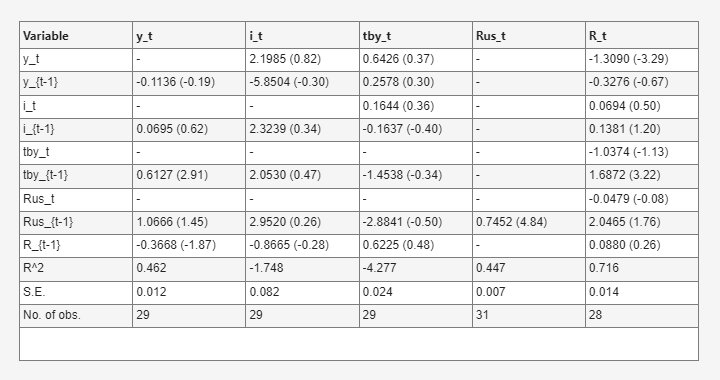


-- Equation [y Ecuador], n=26, k=5, within R^2=0.746 --
   loginvdsalag       coef= 0.4550  se=0.1881  t= 2.42
   tbysalag           coef= 0.5489  se=0.1750  t= 3.14
   logruslag          coef= 2.8285  se=1.1854  t= 2.39
   logilag            coef=-0.2488  se=0.1252  t=-1.99
   logydsalag(IV)     coef=-0.8457  se=0.9380  t=-0.90



-- Equation [i Ecuador], n=26, k=6, within R^2=0.844 --
   logydsa            coef= 8.2636  se=2.2653  t= 3.65
   logydsalag         coef=-1.2134  se=1.9485  t=-0.62
   tbysalag           coef=-3.0184  se=1.5940  t=-1.89
   logruslag          coef=-13.9483  se=6.7059  t=-2.08
   logilag            coef= 0.8790  se=0.4559  t= 1.93
   loginvdsalag(IV)   coef=-1.1498  se=1.0396  t=-1.11



-- Equation [tb/y Ecuador], n=26, k=7, within R^2=0.941 --
   logydsa            coef= 0.6368  se=0.9004  t= 0.71
   logydsalag         coef=-0.0872  se=0.5101  t=-0.17
   loginvdsa          coef=-0.3808  se=0.0821  t=-4.64
   loginvdsalag       coef= 0.0416  se=0.2526  t= 0.16
   logruslag          coef=-1.9975  se=1.8484  t=-1.08
   logilag            coef= 0.1493  se=0.1309  t= 1.14
   tbysalag(IV)       coef= 0.3023  se=0.5173  t= 0.58



   *** WARNING [R Ecuador]: n=25 is small relative to k=9 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [R Ecuador], n=25, k=9, within R^2=0.741 --
   logydsa            coef=-4.0352  se=11.6208  t=-0.35
   logydsalag         coef=-1.0122  se=3.1942  t=-0.32
   loginvdsa          coef= 0.8615  se=2.0742  t= 0.42
   loginvdsalag       coef=-0.2605  se=1.4670  t=-0.18
   tbysa              coef= 1.0987  se=2.7403  t= 0.40
   tbysalag           coef=-0.4271  se=2.5339  t=-0.17
   logrus             coef= 0.8167  se=8.2558  t= 0.10
   logruslag          coef= 7.1331  se=17.7409  t= 0.40
   logilag(IV)        coef=-0.6279  se=3.5265  t=-0.18



============ TABLE 6.1.Ecuador ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      8.2636      0.6368           -     -4.0352
                              (3.65)      (0.71)                 (-0.35)
y_{t-1}          -0.8457     -1.2134     -0.0872           -     -1.0122
                 (-0.90)     (-0.62)     (-0.17)                 (-0.32)
i_t                    -           -     -0.3808           -      0.8615
                                         (-4.64)                  (0.42)
i_{t-1}           0.4550     -1.1498      0.0416           -     -0.2605
                  (2.42)     (-1.11)      (0.16)                 (-0.18)
tby_t                  -           -           -           -      1.0987
                                                                  (0.40)
tby_{t-1}         0.5489     -3.0184      0.3023           -     -0.4271
                  (3.14)     (-1.89)      (0.58)                 (-0.17)
Rus_t                  -           -           -  

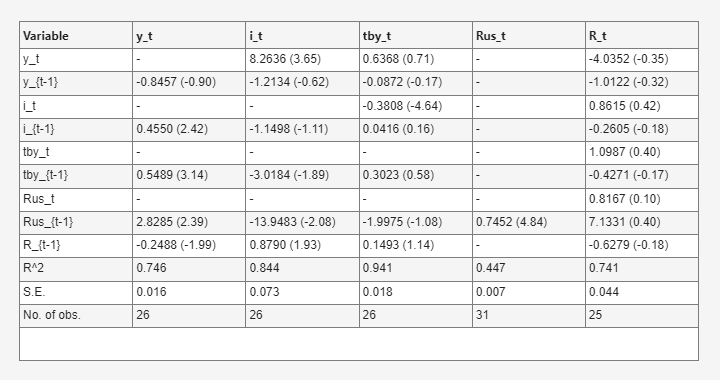


-- Equation [y Mexico], n=30, k=5, within R^2=0.695 --
   loginvdsalag       coef= 0.3049  se=0.1144  t= 2.67
   tbysalag           coef=-0.3580  se=0.6937  t=-0.52
   logruslag          coef= 0.0355  se=0.7496  t= 0.05
   logilag            coef=-0.2818  se=0.1845  t=-1.53
   logydsalag(IV)     coef=-0.5327  se=0.6564  t=-0.81



-- Equation [i Mexico], n=30, k=6, within R^2=0.904 --
   logydsa            coef= 3.2242  se=0.7429  t= 4.34
   logydsalag         coef=-1.8435  se=0.8229  t=-2.24
   tbysalag           coef=-1.1667  se=1.5741  t=-0.74
   logruslag          coef= 1.6990  se=2.1484  t= 0.79
   logilag            coef=-0.1625  se=0.3162  t=-0.51
   loginvdsalag(IV)   coef= 0.2306  se=0.6361  t= 0.36



-- Equation [tb/y Mexico], n=30, k=7, within R^2=0.928 --
   logydsa            coef=-0.4127  se=0.1693  t=-2.44
   logydsalag         coef= 0.4501  se=0.1964  t= 2.29
   loginvdsa          coef= 0.0094  se=0.0614  t= 0.15
   loginvdsalag       coef=-0.0287  se=0.0732  t=-0.39
   logruslag          coef= 0.0015  se=0.2716  t= 0.01
   logilag            coef= 0.1423  se=0.0578  t= 2.46
   tbysalag(IV)       coef= 0.7746  se=0.2373  t= 3.26



-- Equation [R Mexico], n=30, k=9, within R^2=0.801 --
   logydsa            coef=-0.8750  se=0.7881  t=-1.11
   logydsalag         coef= 0.4109  se=1.4158  t= 0.29
   loginvdsa          coef= 0.1489  se=0.2744  t= 0.54
   loginvdsalag       coef=-0.1335  se=0.2492  t=-0.54
   tbysa              coef= 0.6799  se=0.9776  t= 0.70
   tbysalag           coef=-1.0633  se=1.2257  t=-0.87
   logrus             coef= 0.9239  se=1.1463  t= 0.81
   logruslag          coef= 0.5272  se=0.7025  t= 0.75
   logilag(IV)        coef= 0.5053  se=0.8895  t= 0.57



============ TABLE 6.1.Mexico ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      3.2242     -0.4127           -     -0.8750
                              (4.34)     (-2.44)                 (-1.11)
y_{t-1}          -0.5327     -1.8435      0.4501           -      0.4109
                 (-0.81)     (-2.24)      (2.29)                  (0.29)
i_t                    -           -      0.0094           -      0.1489
                                          (0.15)                  (0.54)
i_{t-1}           0.3049      0.2306     -0.0287           -     -0.1335
                  (2.67)      (0.36)     (-0.39)                 (-0.54)
tby_t                  -           -           -           -      0.6799
                                                                  (0.70)
tby_{t-1}        -0.3580     -1.1667      0.7746           -     -1.0633
                 (-0.52)     (-0.74)      (3.26)                 (-0.87)
Rus_t                  -           -           -  

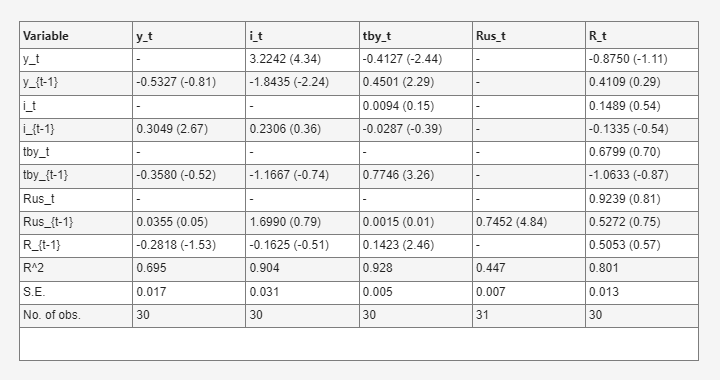


-- Equation [y Peru], n=18, k=5, within R^2=0.742 --
   loginvdsalag       coef= 0.3338  se=0.2194  t= 1.52
   tbysalag           coef= 0.7009  se=0.5736  t= 1.22
   logruslag          coef=-0.2818  se=0.7488  t=-0.38
   logilag            coef=-0.6635  se=0.6974  t=-0.95
   logydsalag(IV)     coef=-0.2923  se=0.8477  t=-0.34



-- Equation [i Peru], n=18, k=6, within R^2=0.878 --
   logydsa            coef= 0.8011  se=1.0051  t= 0.80
   logydsalag         coef=-0.2914  se=0.9060  t=-0.32
   tbysalag           coef= 0.3894  se=1.3187  t= 0.30
   logruslag          coef=-0.6269  se=2.1154  t=-0.30
   logilag            coef=-0.9423  se=1.2152  t=-0.78
   loginvdsalag(IV)   coef= 0.8796  se=0.4519  t= 1.95



   *** WARNING [tb/y Peru]: n=18 is small relative to k=7 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [tb/y Peru], n=18, k=7, within R^2=0.741 --
   logydsa            coef= 0.0606  se=0.2236  t= 0.27
   logydsalag         coef=-0.1021  se=0.1966  t=-0.52
   loginvdsa          coef=-0.0782  se=0.0651  t=-1.20
   loginvdsalag       coef= 0.0488  se=0.1056  t= 0.46
   logruslag          coef=-0.2187  se=0.4566  t=-0.48
   logilag            coef= 0.3213  se=0.3059  t= 1.05
   tbysalag(IV)       coef= 0.4032  se=0.4097  t= 0.98



   *** WARNING [R Peru]: n=17 is small relative to k=9 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [R Peru], n=17, k=9, within R^2=0.304 --
   logydsa            coef=-0.6709  se=0.6682  t=-1.00
   logydsalag         coef=-0.6392  se=0.8918  t=-0.72
   loginvdsa          coef= 0.0222  se=0.1368  t= 0.16
   loginvdsalag       coef= 0.2294  se=0.3415  t= 0.67
   tbysa              coef= 0.6598  se=0.8924  t= 0.74
   tbysalag           coef= 0.3209  se=0.8484  t= 0.38
   logrus             coef= 0.0124  se=1.0750  t= 0.01
   logruslag          coef= 2.1770  se=2.5484  t= 0.85
   logilag(IV)        coef=-1.3384  se=2.3232  t=-0.58



============ TABLE 6.1.Peru ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      0.8011      0.0606           -     -0.6709
                              (0.80)      (0.27)                 (-1.00)
y_{t-1}          -0.2923     -0.2914     -0.1021           -     -0.6392
                 (-0.34)     (-0.32)     (-0.52)                 (-0.72)
i_t                    -           -     -0.0782           -      0.0222
                                         (-1.20)                  (0.16)
i_{t-1}           0.3338      0.8796      0.0488           -      0.2294
                  (1.52)      (1.95)      (0.46)                  (0.67)
tby_t                  -           -           -           -      0.6598
                                                                  (0.74)
tby_{t-1}         0.7009      0.3894      0.4032           -      0.3209
                  (1.22)      (0.30)      (0.98)                  (0.38)
Rus_t                  -           -           -  

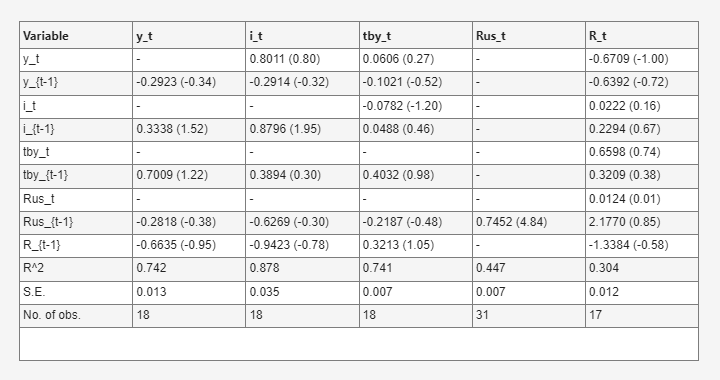


   *** WARNING [y Philippines]: n=9 is small relative to k=5 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [y Philippines], n=9, k=5, within R^2=-104.515 --
   loginvdsalag       coef= 1.4793  se=9.6950  t= 0.15
   tbysalag           coef= 4.8346  se=33.4365  t= 0.14
   logruslag          coef=-23.7722  se=164.2841  t=-0.14
   logilag            coef=-1.0408  se=7.1271  t=-0.15
   logydsalag(IV)     coef=-15.0763  se=105.0078  t=-0.14



   *** WARNING [i Philippines]: n=9 is small relative to k=6 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [i Philippines], n=9, k=6, within R^2=-5.912 --
   logydsa            coef=-4.5409  se=17.9168  t=-0.25
   logydsalag         coef=-5.2322  se=29.6427  t=-0.18
   tbysalag           coef= 2.5749  se=12.2282  t= 0.21
   logruslag          coef=-12.8541  se=63.5971  t=-0.20
   logilag            coef=-0.8189  se=4.8901  t=-0.17
   loginvdsalag(IV)   coef= 2.9190  se=9.7828  t= 0.30



   *** WARNING [tb/y Philippines]: n=9 is small relative to k=7 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [tb/y Philippines], n=9, k=7, within R^2=0.665 --
   logydsa            coef=-3.1438  se=5.0502  t=-0.62
   logydsalag         coef=-4.6850  se=21.8789  t=-0.21
   loginvdsa          coef= 0.7581  se=2.1797  t= 0.35
   loginvdsalag       coef= 1.7294  se=3.0823  t= 0.56
   logruslag          coef=-13.7217  se=46.1367  t=-0.30
   logilag            coef=-3.3305  se=2.3037  t=-1.45
   tbysalag(IV)       coef= 3.5969  se=8.9753  t= 0.40



   *** WARNING [R Philippines]: n=8 is small relative to k=9 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [R Philippines], n=8, k=9, within R^2=1.000 --
   logydsa            coef=-1.1113  se=0.0000  t=-89835501697963.98
   logydsalag         coef= 0.2881  se=0.0000  t= 40189175954206.40
   loginvdsa          coef=-0.0448  se=0.0000  t=-17590716268399.31
   loginvdsalag       coef= 0.2722  se=0.0000  t= 78168699526138.77
   tbysa              coef= 0.0292  se=0.0000  t= 12182550678893.46
   tbysalag           coef=-0.0037  se=0.0000  t=-1033320210961.40
   logrus             coef= 0.5976  se=0.0000  t= 115119321794212.30
   logruslag          coef=-0.2403  se=0.0000  t=-39732088629848.20
   logilag(IV)        coef= 0.4308  se=0.0000  t= 60055486414445.80



============ TABLE 6.1.Philippines ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -     -4.5409     -3.1438           -     -1.1113
                             (-0.25)     (-0.62)            (-89835501697963.98)
y_{t-1}         -15.0763     -5.2322     -4.6850           -      0.2881
                 (-0.14)     (-0.18)     (-0.21)            (40189175954206.40)
i_t                    -           -      0.7581           -     -0.0448
                                          (0.35)            (-17590716268399.31)
i_{t-1}           1.4793      2.9190      1.7294           -      0.2722
                  (0.15)      (0.30)      (0.56)            (78168699526138.77)
tby_t                  -           -           -           -      0.0292
                                                            (12182550678893.46)
tby_{t-1}         4.8346      2.5749      3.5969           -     -0.0037
                  (0.14)      (0.21)      (0.40)            (-1033320210961.40)
Rus_t 

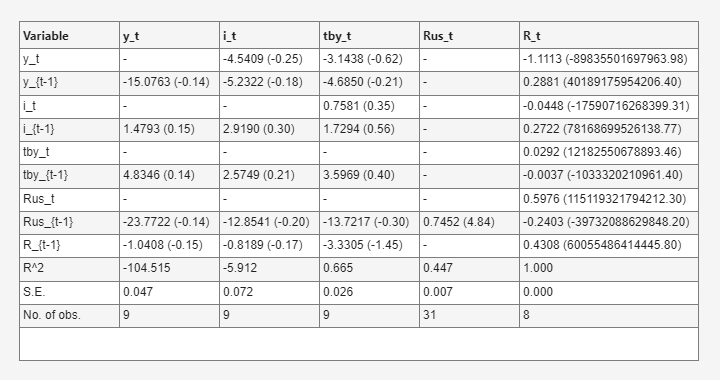


-- Equation [y South_Africa], n=27, k=5, within R^2=0.834 --
   loginvdsalag       coef=-0.0297  se=0.0267  t=-1.11
   tbysalag           coef=-0.1185  se=0.1731  t=-0.68
   logruslag          coef=-0.2181  se=0.2081  t=-1.05
   logilag            coef= 0.0560  se=0.1399  t= 0.40
   logydsalag(IV)     coef= 0.8161  se=0.1084  t= 7.53



-- Equation [i South_Africa], n=27, k=6, within R^2=0.865 --
   logydsa            coef= 0.1119  se=1.0291  t= 0.11
   logydsalag         coef= 1.0887  se=1.1077  t= 0.98
   tbysalag           coef=-0.0074  se=0.8306  t=-0.01
   logruslag          coef= 0.7770  se=0.9394  t= 0.83
   logilag            coef= 0.4542  se=0.6306  t= 0.72
   loginvdsalag(IV)   coef= 0.7970  se=0.1417  t= 5.62



-- Equation [tb/y South_Africa], n=27, k=7, within R^2=0.550 --
   logydsa            coef= 0.3561  se=0.2969  t= 1.20
   logydsalag         coef=-0.1235  se=0.3248  t=-0.38
   loginvdsa          coef=-0.2347  se=0.0609  t=-3.86
   loginvdsalag       coef= 0.1445  se=0.0768  t= 1.88
   logruslag          coef= 0.3362  se=0.2624  t= 1.28
   logilag            coef=-0.1662  se=0.2158  t=-0.77
   tbysalag(IV)       coef=-0.1057  se=0.4240  t=-0.25



   *** WARNING [R South_Africa]: n=26 is small relative to k=9 parameters --
   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***

-- Equation [R South_Africa], n=26, k=9, within R^2=0.992 --
   logydsa            coef= 0.0557  se=0.0674  t= 0.83
   logydsalag         coef=-0.0970  se=0.0701  t=-1.38
   loginvdsa          coef= 0.0238  se=0.0175  t= 1.36
   loginvdsalag       coef=-0.0164  se=0.0161  t=-1.02
   tbysa              coef= 0.0307  se=0.0505  t= 0.61
   tbysalag           coef= 0.0197  se=0.0506  t= 0.39
   logrus             coef= 1.0317  se=0.0349  t= 29.55
   logruslag          coef=-0.7764  se=0.0760  t=-10.22
   logilag(IV)        coef= 0.7002  se=0.0499  t= 14.03



============ TABLE 6.1.South_Africa ============



Variable             y_t         i_t       tby_t       Rus_t         R_t
y_t                    -      0.1119      0.3561           -      0.0557
                              (0.11)      (1.20)                  (0.83)
y_{t-1}           0.8161      1.0887     -0.1235           -     -0.0970
                  (7.53)      (0.98)     (-0.38)                 (-1.38)
i_t                    -           -     -0.2347           -      0.0238
                                         (-3.86)                  (1.36)
i_{t-1}          -0.0297      0.7970      0.1445           -     -0.0164
                 (-1.11)      (5.62)      (1.88)                 (-1.02)
tby_t                  -           -           -           -      0.0307
                                                                  (0.61)
tby_{t-1}        -0.1185     -0.0074     -0.1057           -      0.0197
                 (-0.68)     (-0.01)     (-0.25)                  (0.39)
Rus_t                  -           -           -  

country_codes = [213, 223, 248, 273, 293, 566, 199];
country_names = {'Argentina','Brazil','Ecuador','Mexico','Peru','Philippines','South_Africa'};

for k = 1:numel(country_codes)
    cc = country_codes(k); cname = country_names{k};
    m = code==cc;

    [cb1, cse1, cres1, ~, cr2_1] = panel_fe_iv(logydsa(m), ...
        {loginvdsalag(m), tbysalag(m), logruslag(m), logilag(m)}, logydsalag(m), logydsalag2(m), code(m), ...
        {'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, ['y ' cname]);
    [cb2, cse2, cres2, ~, cr2_2] = panel_fe_iv(loginvdsa(m), ...
        {logydsa(m), logydsalag(m), tbysalag(m), logruslag(m), logilag(m)}, loginvdsalag(m), panel_lag(loginvdsa(m),code(m),2), code(m), ...
        {'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, ['i ' cname]);
    [cb3, cse3, cres3, ~, cr2_3] = panel_fe_iv(tbysa(m), ...
        {logydsa(m), logydsalag(m), loginvdsa(m), panel_lag(loginvdsa(m),code(m),1), logruslag(m), logilag(m)}, tbysalag(m), panel_lag(tbysa(m),code(m),2), code(m), ...
        {'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, ['tb/y ' cname]);
    [cb5, cse5, cres5, ~, cr2_5] = panel_fe_iv(logi(m), ...
        {logydsa(m), logydsalag(m), loginvdsa(m), panel_lag(loginvdsa(m),code(m),1), tbysa(m), tbysalag(m), logrus(m), logruslag(m)}, logilag(m), logilag2(m), code(m), ...
        {'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, ['R ' cname]);

    [cc1,ct1] = map_to_rows({'loginvdsalag','tbysalag','logruslag','logilag','logydsalag(IV)'}, cb1, cse1, rowmap);
    [cc2,ct2] = map_to_rows({'logydsa','logydsalag','tbysalag','logruslag','logilag','loginvdsalag(IV)'}, cb2, cse2, rowmap);
    [cc3,ct3] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','logruslag','logilag','tbysalag(IV)'}, cb3, cse3, rowmap);
    [cc5,ct5] = map_to_rows({'logydsa','logydsalag','loginvdsa','loginvdsalag','tbysa','tbysalag','logrus','logruslag','logilag(IV)'}, cb5, cse5, rowmap);

    coefmat_c  = [cc1, cc2, cc3, c4, cc5];      % Rus column (c4) reused from 6.1.A -- see note above
    tstatmat_c = [ct1, ct2, ct3, t4, ct5];
    r2vec_c    = [cr2_1, cr2_2, cr2_3, r2_ar1_A, cr2_5];
    nobsvec_c  = [numel(cres1), numel(cres2), numel(cres3), nA, numel(cres5)];
    sevec_c    = [std(cres1), std(cres2), std(cres3), std(res_ar1_A), std(cres5)];

    fprintf('\n============ TABLE 6.1.%s ============\n', cname);
    print_table61(rownames, colnames, coefmat_c, tstatmat_c, r2vec_c, sevec_c, nobsvec_c);
    figure_table61(rownames, colnames, coefmat_c, tstatmat_c, r2vec_c, sevec_c, nobsvec_c, ['Table 6.1.' cname]);
end

*What changes, table to table, in Section 5:*  * Each country's N drops to roughly its own available quarters (~26-30) instead of the panel's pooled 160-165 -- standard errors widen a lot, so one should expect many coefficients to lose significance individually even where the panel found a strong effect. * No country fixed effect is being averaged away against seven other countries anymore -- each table reflects that country's own dynamics only, so don't expect any two country tables to look alike. * The Rus column is identical across every country table (and equal to 6.1.A) since Rus is a common variable with no country dimension -- it's included here for layout consistency with the book's table, not because it was re-estimated. 

## Local functions

function IRF = compute_irf(Ainv, Phi, shock_idx, H)

Standard recursive/Cholesky-SVAR IRF: impact vector A^{-1}*e_j, then iterate the reduced-form companion matrix Phi = A^{-1}*B forward. Returns an (H+1) x 5 matrix, columns ordered [y, i, tby, rus, R].

    e = zeros(5,1); e(shock_idx) = 1;
    z = Ainv * e;
    IRF = z';
    for h = 1:H
        z = Phi * z;
        IRF = [IRF; z']; %#ok<AGROW>
    end
end

function xl = panel_lag(x, id, n)
    xl = nan(size(x));
    for i = (n+1):length(x)
        if id(i) == id(i-n)
            xl(i) = x(i-n);
        end
    end
end

function [beta, se, resid, samp, r2] = panel_fe_iv(y, exog_cell, endog, instr, id, names, eqname)
    allvars = [{y, endog, instr}, exog_cell];
    samp = true(size(y));
    for k = 1:numel(allvars)
        samp = samp & ~isnan(allvars{k});
    end
    idS = id(samp); yS = y(samp); endogS = endog(samp); instrS = instr(samp);
    exogS = cellfun(@(v) v(samp), exog_cell, 'UniformOutput', false);

    yD     = demean_by_group(yS, idS);
    endogD = demean_by_group(endogS, idS);
    instrD = demean_by_group(instrS, idS);
    exogD  = cellfun(@(v) demean_by_group(v, idS), exogS, 'UniformOutput', false);

    if isempty(exogD)
        X = endogD; Z = instrD;
    else
        X = [horzcat(exogD{:}), endogD];
        Z = [horzcat(exogD{:}), instrD];
    end

    PZ    = Z*pinv(Z'*Z)*Z';
    Xhat  = PZ*X;
    beta  = pinv(Xhat'*X)*(Xhat'*yD);
    resid = yD - X*beta;

    n = size(X,1); k = size(X,2);
    dof = max(n-k, 1);
    sigma2 = (resid'*resid)/dof;
    varb = sigma2*pinv(Xhat'*X);
    se = sqrt(diag(varb));

    r2 = 1 - sum(resid.^2) / sum((yD - mean(yD)).^2);

    if nargin < 7, eqname = ''; end
    if n < 3*k
        fprintf('\n   *** WARNING [%s]: n=%d is small relative to k=%d parameters --\n', eqname, n, k);
        fprintf('   *** results below are likely unreliable/near-degenerate (e.g. R^2 far outside [0,1]). ***\n');
    end
    fprintf('\n-- Equation [%s], n=%d, k=%d, within R^2=%.3f --\n', eqname, n, k, r2);
    for j = 1:k
        lbl = '?'; if j<=numel(names), lbl = names{j}; end
        fprintf('   %-18s coef=% .4f  se=%.4f  t=% .2f\n', lbl, beta(j), se(j), beta(j)/se(j));
    end
end

function xd = demean_by_group(x, id)
    xd = x; u = unique(id);
    for i = 1:numel(u)
        idx = id==u(i);
        xd(idx) = x(idx) - mean(x(idx));
    end
end

function [colcoef, coltstat] = map_to_rows(names, beta, se, rowmap)
    colcoef = nan(9,1); coltstat = nan(9,1);
    for j = 1:numel(names)
        nm = strrep(names{j}, '(IV)', '');
        if isKey(rowmap, nm)
            r = rowmap(nm);
            colcoef(r)  = beta(j);
            coltstat(r) = beta(j)/se(j);
        end
    end
end

function print_table61(rownames, colnames, coef, tstat, r2, se_eq, nobs)
    fprintf('\n%-12s', 'Variable');
    for c = 1:numel(colnames), fprintf('%12s', colnames{c}); end
    fprintf('\n');
    for rr = 1:numel(rownames)
        fprintf('%-12s', rownames{rr});
        for c = 1:size(coef,2)
            if isnan(coef(rr,c)), fprintf('%12s', '-');
            else, fprintf('%12.4f', coef(rr,c)); end
        end
        fprintf('\n%-12s', '');
        for c = 1:size(coef,2)
            if isnan(tstat(rr,c)), fprintf('%12s', '');
            else, fprintf('%12s', sprintf('(%.2f)', tstat(rr,c))); end
        end
        fprintf('\n');
    end
    fprintf('%-12s', 'R^2');
    for c = 1:numel(r2), fprintf('%12.3f', r2(c)); end
    fprintf('\n%-12s', 'S.E.');
    for c = 1:numel(se_eq), fprintf('%12.3f', se_eq(c)); end
    fprintf('\n%-12s', 'No. of obs.');
    for c = 1:numel(nobs), fprintf('%12d', nobs(c)); end
    fprintf('\n');
end

function figure_table61(rownames, colnames, coef, tstat, r2, se_eq, nobs, titlestr)

Same content as print_table61, but rendered as a uitable in its own window instead of monospaced text in the Command Window / Live Editor output. Each cell shows "coefficient (t-stat)", matching the book's layout, with R^2 / S.E. / N as extra rows at the bottom.

    if nargin < 8, titlestr = 'Table 6.1'; end
    nR = numel(rownames); nC = numel(colnames);
    data = cell(nR+3, nC+1);
    data(1:nR,1) = rownames(:);
    data{nR+1,1} = 'R^2';
    data{nR+2,1} = 'S.E.';
    data{nR+3,1} = 'No. of obs.';
    for c = 1:nC
        for r = 1:nR
            if isnan(coef(r,c))
                data{r,c+1} = '-';
            else
                data{r,c+1} = sprintf('%.4f (%.2f)', coef(r,c), tstat(r,c));
            end
        end
        data{nR+1,c+1} = sprintf('%.3f', r2(c));
        data{nR+2,c+1} = sprintf('%.3f', se_eq(c));
        data{nR+3,c+1} = sprintf('%d', nobs(c));
    end
    fig = uifigure('Name', titlestr, 'Position', [100 100 720 380]);
    uitable(fig, 'Data', data, ...
        'ColumnName', [{'Variable'}, colnames], ...
        'RowName', {}, ...
        'Position', [20 20 680 340]);
end
